 This script look at the performance of ResNet at predicting vocalizations

 and noise.

First look at performance at the level of 100ms windows

PredTruth is a 2 row matrix of all 100ms windows for all loggers accross all sequences with first row the identity of the window as Noise vs Vocalization according to manual curation; the second row is the ResNet posterior probability of a vocalization

FS= 50000;
WinSize  = 100/1000*FS;

Date = {'200130'; '200131'};
ExpStartTime = {'0949'; '1009'};
FileRange = {36:44 1:10};
PredTruth = cell(size(FileRange));
for dd=1:length(Date)
    fprintf(1,'Date %s   ', Date{dd})
    Loggers_dir = sprintf('/Volumes/server_home/users/JulieE/DeafSalineGroup151/20%s/audiologgers', Date{dd});
    ResNetDataFile = dir(fullfile(Loggers_dir, sprintf('*%s.csv', Date{dd})));
    ResNetData = readtable(fullfile(ResNetDataFile.folder, ResNetDataFile.name), 'Delimiter',',');
    Discrepency=[];
    PredTruth{dd} = cell(size(FileRange{dd}));
    for dfL=1:length(FileRange{dd})
        df = FileRange{dd}(dfL);
        fprintf(1,'\nFile %d/%d', df, max(FileRange{dd}))
        Filename = sprintf('%s_%s_VocExtractData%d_200.mat', Date{dd}, ExpStartTime{dd}, df);
        DataFile1 = fullfile(Loggers_dir, Filename);
        load(DataFile1, 'IndVocStartPiezo_merged', 'IndVocStopPiezo_merged', 'IndVocStartPiezo', 'IndVocStopPiezo');
        DataFile2 = fullfile(Loggers_dir, sprintf('%s_%s_VocExtractData%d.mat', Date{dd}, ExpStartTime{dd}, df));
        load(DataFile2, 'Piezo_wave', 'VocFilename')
        Fns_AL = fieldnames(Piezo_wave);
        PredTruth{dd}{dfL} = cell(1,length(IndVocStartPiezo_merged));
        for vv=1:length(IndVocStartPiezo_merged)
            if ~rem(vv,10)
                fprintf(1,'Voc %d/%d...', vv,length(IndVocStartPiezo_merged))
            end
            PredTruth{dd}{dfL}{vv} = cell(1,length(Fns_AL));
            for ll=1:length(Fns_AL)
                RowsData = logical(contains(ResNetData.Var1(:), sprintf('15120%s%s_%d_%s_', Date{dd}, Filename(1:11), df,Fns_AL{ll})) .*contains(ResNetData.Var1(:), sprintf('_%d.mat', vv-1))); % ResNetData.Var1 referes to files with a zero indexing
                pVoclogger = ResNetData.Var3(RowsData)'; % all probability of a vocalization across all 100ms windows of that logger on that sequence
                VocVector = zeros(1,ceil(length(Piezo_wave.(Fns_AL{ll}){vv})/FS*10)); % This is a vector of the smae size as the number of 100ms window that could fit in that sequence
                if ~isempty(IndVocStartPiezo_merged{vv})
                    for ii=1:length(IndVocStartPiezo_merged{vv}{ll})
                        IndVocStart = ceil(IndVocStartPiezo_merged{vv}{ll}(ii)/FS*10);
                        IndVocStop = floor(IndVocStopPiezo_merged{vv}{ll}(ii)/FS*10);
                        VocVector(IndVocStart:IndVocStop) = ones(size(IndVocStart:IndVocStop));
                    end
                end
                Discrepency = [Discrepency length(VocVector)-length(pVoclogger)];
                if Discrepency(end)
                    keyboard
                end
                PredTruth{dd}{dfL}{vv}{ll} = [VocVector ; pVoclogger(1:length(VocVector))];
            end
            PredTruth{dd}{dfL}{vv} = [PredTruth{dd}{dfL}{vv}{:}];
        end
        PredTruth{dd}{dfL} = [PredTruth{dd}{dfL}{:}];
    end
    PredTruth{dd} = [PredTruth{dd}{:}];
end

Date 200130   


File 36/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 37/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 38/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 39/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 40/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 41/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 42/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 43/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 44/44

Voc 10/39...Voc 20/39...Voc 30/39...

Date 200131   


File 1/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 2/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 3/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 4/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 5/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 6/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 7/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 8/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 9/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 10/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...

PredTruth = [PredTruth{:}];

figure()
swarmchart(PredTruth(1,:), PredTruth(2,:))
set(gca, 'XTick', [0 1],'XTickLabels', {'Noise' 'Voc'})
xlabel('Manual annotation')
ylabel('ResNet Probability of a vocalization')

fprintf(1, 'Correct classification of noise with Posterior proba of 0.5: %d/%d, %.2f%%\n', sum(PredTruth(2,~PredTruth(1,:))<0.5),sum(~PredTruth(1,:)), sum(PredTruth(2,~PredTruth(1,:))<0.5)/sum(~PredTruth(1,:))*100)

Correct classification of noise with Posterior proba of 0.5: 228039/234908, 97.08%


fprintf(1, 'Correct classification of Vocalizations with Posterior proba of 0.5: %d/%d, %.2f%%\n', sum(PredTruth(2,logical(PredTruth(1,:)))>0.5),sum(PredTruth(1,:)), sum(PredTruth(2,logical(PredTruth(1,:)))>0.5)/sum(PredTruth(1,:))*100)

Correct classification of Vocalizations with Posterior proba of 0.5: 1190/1332, 89.34%


PostProba = 0:0.01:0.5;
PCC=nan(2,length(PostProba));
for pp=1:length(PostProba)
    PCC(1,pp) = sum(PredTruth(2,~PredTruth(1,:))<PostProba(pp))/sum(~PredTruth(1,:));
    PCC(2,pp) = sum(PredTruth(2,logical(PredTruth(1,:)))>PostProba(pp))/sum(logical(PredTruth(1,:)));
end
figure()
plot(PostProba,PCC', 'LineWidth',2)
legend({'Noise' 'Vocalization'})
xlabel('ResNet Posterior probability')
ylabel('Probability of correct classification of 100ms windows')

Now get the performance at the level of sequences: where should we set the threshold of max posterior probability in Who_calls_play_less to get rid of most noise but not miss vocalizations?

PredTruthSeq is a 2 row matrix with the first row the actual Noise vs Vocalization manual curation coding of the whole sequence (there is at least 1 call on one logger); the second row is the max over all posterior probabilities of a vocalization given by ResNet across all 100ms windows of all loggers on each sequence. Each column = 1 sequence

PredTruthSeq = cell(size(FileRange));
for dd=1:length(Date)
    fprintf(1,'Date %s   ', Date{dd})
    Loggers_dir = sprintf('/Volumes/server_home/users/JulieE/DeafSalineGroup151/20%s/audiologgers', Date{dd});
    ResNetDataFile = dir(fullfile(Loggers_dir, sprintf('*%s.csv', Date{dd})));
    ResNetData = readtable(fullfile(ResNetDataFile.folder, ResNetDataFile.name), 'Delimiter',',');
    PredTruthSeq{dd} = cell(size(FileRange{dd}));
    for dfL=1:length(FileRange{dd})
        df = FileRange{dd}(dfL);
        fprintf(1,'\nFile %d/%d', df, max(FileRange{dd}))
        Filename = sprintf('%s_%s_VocExtractData%d_200.mat', Date{dd}, ExpStartTime{dd}, df);
        DataFile1 = fullfile(Loggers_dir, Filename);
        load(DataFile1, 'IndVocStartPiezo_merged', 'IndVocStopPiezo_merged', 'IndVocStartPiezo', 'IndVocStopPiezo');
        DataFile2 = fullfile(Loggers_dir, sprintf('%s_%s_VocExtractData%d.mat', Date{dd}, ExpStartTime{dd}, df));
        load(DataFile2, 'Piezo_wave', 'VocFilename')
        Fns_AL = fieldnames(Piezo_wave);
        PredTruthSeq{dd}{dfL} = nan(2,length(IndVocStartPiezo_merged));
        for vv=1:length(IndVocStartPiezo_merged)
            if ~rem(vv,10)
                fprintf(1,'Voc %d/%d...', vv,length(IndVocStartPiezo_merged))
            end
            RowsData = logical(contains(ResNetData.Var1(:), sprintf('15120%s%s_%d_Logger', Date{dd}, Filename(1:11), df)) .*contains(ResNetData.Var1(:), sprintf('_%d.mat', vv-1))); % ResNetData.Var1 referes to files with a zero indexing
            pVoclogger = max(ResNetData.Var3(RowsData)); % max over all probabilities of a vocalization across all 100ms windows of all loggers on that sequence
            VocTruth = 0;
            if ~isempty(IndVocStartPiezo_merged{vv})
                for ll=1:length(Fns_AL)
                    if ~isempty(IndVocStartPiezo_merged{vv}{ll})
                        VocTruth = 1;
                        break
                    end
                end
            end
            PredTruthSeq{dd}{dfL}(:,vv) = [VocTruth; pVoclogger];
        end
    end
    PredTruthSeq{dd} = [PredTruthSeq{dd}{:}];
end

Date 200130   


File 36/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 37/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 38/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 39/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 40/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 41/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 42/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 43/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 44/44

Voc 10/39...Voc 20/39...Voc 30/39...

Date 200131   


File 1/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 2/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 3/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 4/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 5/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 6/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 7/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 8/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 9/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 10/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...

PredTruthSeq = [PredTruthSeq{:}];

figure()
swarmchart(PredTruthSeq(1,:), PredTruthSeq(2,:))
set(gca, 'XTick', [0 1],'XTickLabels', {'Noise' 'Voc'})
xlabel('Manual annotation')
ylabel('ResNet max Probability of a vocalization across loggers per sequence')

fprintf(1, 'Correct classification of noise with Posterior proba of 0.5: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.5),sum(~PredTruthSeq(1,:)), sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.5)/sum(~PredTruthSeq(1,:))*100)

Correct classification of noise with Posterior proba of 0.5: 200/1620, 12.35%


fprintf(1, 'Correct classification of Vocalizations with Posterior proba of 0.5: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.5),sum(PredTruthSeq(1,:)), sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.5)/sum(PredTruthSeq(1,:))*100)

Correct classification of Vocalizations with Posterior proba of 0.5: 219/219, 100.00%


PostProba = 0.8:0.01:1;
PCC=nan(2,length(PostProba));
for pp=1:length(PostProba)
    PCC(1,pp) = sum(PredTruthSeq(2,~PredTruthSeq(1,:))<PostProba(pp))/sum(~PredTruthSeq(1,:));
    PCC(2,pp) = sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>PostProba(pp))/sum(logical(PredTruthSeq(1,:)));
end
figure()
plot(PostProba,PCC', 'LineWidth',2)
legend({'Noise' 'Vocalization'})
xlabel('ResNet Posterior probability')
ylabel('max Probability of correct classification across loggers per sequence')

fprintf(1, 'Correct classification of noise with max Posterior proba of 0.94: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.94),sum(~PredTruthSeq(1,:)), sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.94)/sum(~PredTruthSeq(1,:))*100)

Correct classification of noise with max Posterior proba of 0.94: 963/1620, 59.44%


fprintf(1, 'Correct classification of Vocalizations with max Posterior proba of 0.94: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.94),sum(PredTruthSeq(1,:)), sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.94)/sum(PredTruthSeq(1,:))*100)

Correct classification of Vocalizations with max Posterior proba of 0.94: 217/219, 99.09%


fprintf(1, 'Correct classification of noise with max Posterior proba of 0.9: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.9),sum(~PredTruthSeq(1,:)), sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.9)/sum(~PredTruthSeq(1,:))*100)

Correct classification of noise with max Posterior proba of 0.9: 834/1620, 51.48%


fprintf(1, 'Correct classification of Vocalizations with max Posterior proba of 0.9: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.9),sum(PredTruthSeq(1,:)), sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.9)/sum(PredTruthSeq(1,:))*100)

Correct classification of Vocalizations with max Posterior proba of 0.9: 218/219, 99.54%


fprintf(1, 'Correct classification of noise with max Posterior proba of 0.96: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.96),sum(~PredTruthSeq(1,:)), sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.96)/sum(~PredTruthSeq(1,:))*100)

Correct classification of noise with max Posterior proba of 0.96: 1042/1620, 64.32%


fprintf(1, 'Correct classification of Vocalizations with max Posterior proba of 0.96: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.96),sum(PredTruthSeq(1,:)), sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.96)/sum(PredTruthSeq(1,:))*100)

Correct classification of Vocalizations with max Posterior proba of 0.96: 216/219, 98.63%


fprintf(1, 'Correct classification of noise with max Posterior proba of 0.95: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.95),sum(~PredTruthSeq(1,:)), sum(PredTruthSeq(2,~PredTruthSeq(1,:))<0.95)/sum(~PredTruthSeq(1,:))*100)

Correct classification of noise with max Posterior proba of 0.95: 999/1620, 61.67%


fprintf(1, 'Correct classification of Vocalizations with max Posterior proba of 0.95: %d/%d, %.2f%%\n', sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.95),sum(PredTruthSeq(1,:)), sum(PredTruthSeq(2,logical(PredTruthSeq(1,:)))>0.95)/sum(PredTruthSeq(1,:))*100)

Correct classification of Vocalizations with max Posterior proba of 0.95: 217/219, 99.09%


Now get the performance at the level of sequence for each logger: where should we set the threshold of max posterior probability in Who_calls_play_less to get rid of most noise but not miss vocalizations for each logger?

PredTruthSeqLog is a 2 row matrix with the first row the actual Noise vs Vocalization manual curation coding of the whole sequence for each logger (there is at least 1 call on the logger); the second row is the max over all posterior probabilities of a vocalization given by ResNet across all 100ms windows of that logger on each sequence. Each column = 1 sequence of one logger

PredTruthSeqLog = cell(size(FileRange));
for dd=1:length(Date)
    fprintf(1,'Date %s   ', Date{dd})
    Loggers_dir = sprintf('/Volumes/server_home/users/JulieE/DeafSalineGroup151/20%s/audiologgers', Date{dd});
    ResNetDataFile = dir(fullfile(Loggers_dir, sprintf('*%s.csv', Date{dd})));
    ResNetData = readtable(fullfile(ResNetDataFile.folder, ResNetDataFile.name), 'Delimiter',',');
    PredTruthSeqLog{dd} = cell(size(FileRange{dd}));
    for dfL=1:length(FileRange{dd})
        df = FileRange{dd}(dfL);
        fprintf(1,'\nFile %d/%d', df, max(FileRange{dd}))
        Filename = sprintf('%s_%s_VocExtractData%d_200.mat', Date{dd}, ExpStartTime{dd}, df);
        DataFile1 = fullfile(Loggers_dir, Filename);
        load(DataFile1, 'IndVocStartPiezo_merged', 'IndVocStopPiezo_merged', 'IndVocStartPiezo', 'IndVocStopPiezo');
        DataFile2 = fullfile(Loggers_dir, sprintf('%s_%s_VocExtractData%d.mat', Date{dd}, ExpStartTime{dd}, df));
        load(DataFile2, 'Piezo_wave', 'VocFilename')
        Fns_AL = fieldnames(Piezo_wave);
        PredTruthSeqLog{dd}{dfL} = cell(1,length(IndVocStartPiezo_merged));
        for vv=1:length(IndVocStartPiezo_merged)
            if ~rem(vv,10)
                fprintf(1,'Voc %d/%d...', vv,length(IndVocStartPiezo_merged))
            end
            PredTruthSeqLog{dd}{dfL}{vv} = nan(2,length(Fns_AL));
            for ll=1:length(Fns_AL)
                RowsData = logical(contains(ResNetData.Var1(:), sprintf('15120%s%s_%d_%s_', Date{dd}, Filename(1:11), df, Fns_AL{ll})) .*contains(ResNetData.Var1(:), sprintf('_%d.mat', vv-1))); % ResNetData.Var1 referes to files with a zero indexing
                pVoclogger = max(ResNetData.Var3(RowsData)); % max over all probabilities of a vocalization across all 100ms windows of that logger on that sequence
                VocTruth = 0;
                if ~isempty(IndVocStartPiezo_merged{vv})
                    if ~isempty(IndVocStartPiezo_merged{vv}{ll})
                            VocTruth = 1;
                    end
                end
                PredTruthSeqLog{dd}{dfL}{vv}(:,ll) = [VocTruth; pVoclogger];
            end
        end
        PredTruthSeqLog{dd}{dfL} = [PredTruthSeqLog{dd}{dfL}{:}];
    end
    PredTruthSeqLog{dd} = [PredTruthSeqLog{dd}{:}];
end

Date 200130   


File 36/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 37/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 38/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 39/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 40/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 41/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 42/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 43/44

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 44/44

Voc 10/39...Voc 20/39...Voc 30/39...

Date 200131   


File 1/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 2/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 3/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 4/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 5/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 6/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 7/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 8/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 9/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...


File 10/10

Voc 10/100...Voc 20/100...Voc 30/100...Voc 40/100...Voc 50/100...Voc 60/100...Voc 70/100...Voc 80/100...Voc 90/100...Voc 100/100...

PredTruthSeqLog = [PredTruthSeqLog{:}];

figure()
swarmchart(PredTruthSeqLog(1,:), PredTruthSeqLog(2,:))
set(gca, 'XTick', [0 1],'XTickLabels', {'Noise' 'Voc'})
xlabel('Manual annotation')
ylabel('ResNet max Probability of a vocalization within a logger sequence')

fprintf(1, 'Correct classification of noise with Posterior proba of 0.5: %d/%d, %.2f%%\n', sum(PredTruthSeqLog(2,~PredTruthSeqLog(1,:))<0.5),sum(~PredTruthSeqLog(1,:)), sum(PredTruthSeqLog(2,~PredTruthSeqLog(1,:))<0.5)/sum(~PredTruthSeqLog(1,:))*100)

Correct classification of noise with Posterior proba of 0.5: 15370/18113, 84.86%


fprintf(1, 'Correct classification of Vocalizations with Posterior proba of 0.5: %d/%d, %.2f%%\n', sum(PredTruthSeqLog(2,logical(PredTruthSeqLog(1,:)))>0.5),sum(PredTruthSeqLog(1,:)), sum(PredTruthSeqLog(2,logical(PredTruthSeqLog(1,:)))>0.5)/sum(PredTruthSeqLog(1,:))*100)

Correct classification of Vocalizations with Posterior proba of 0.5: 277/277, 100.00%


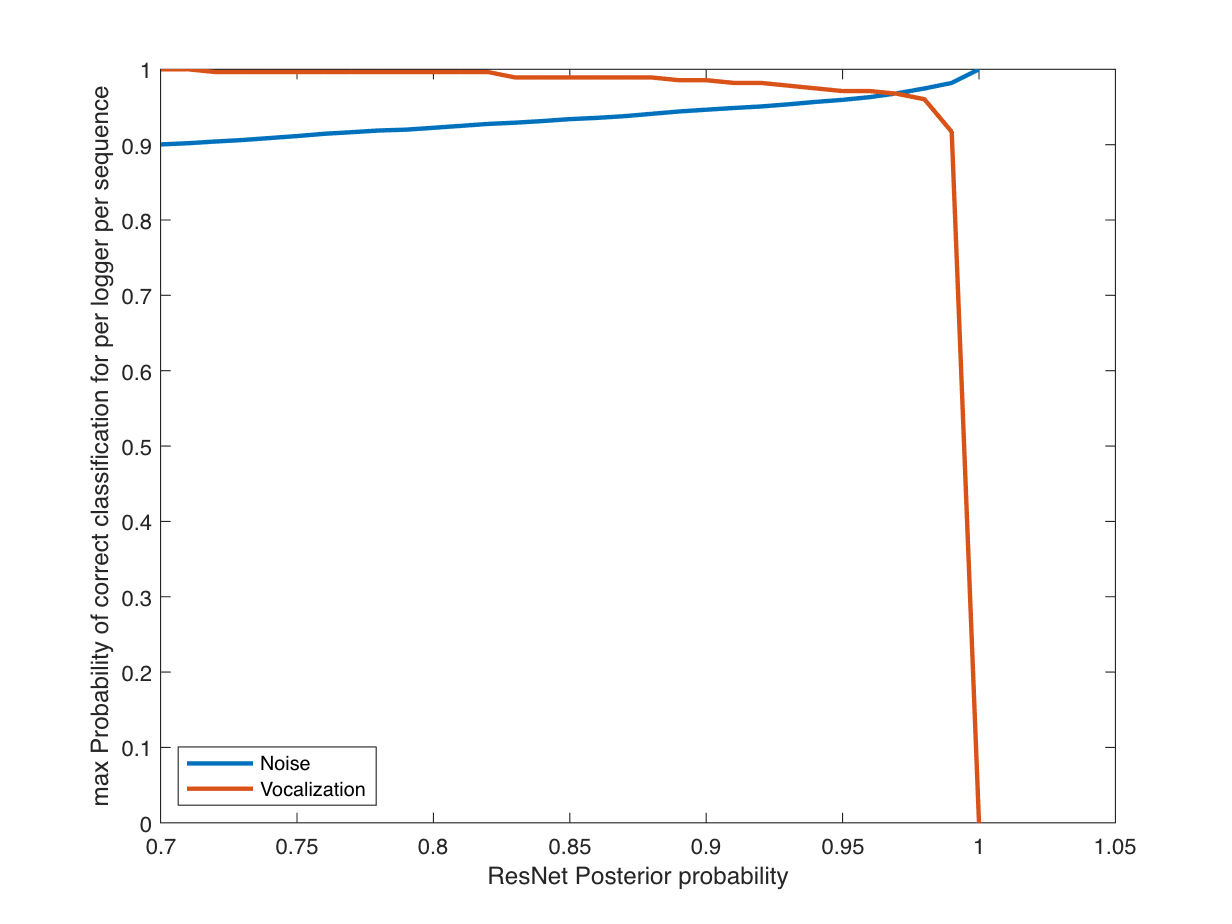

PostProba = 0.7:0.01:1;
PCC=nan(2,length(PostProba));
for pp=1:length(PostProba)
    PCC(1,pp) = sum(PredTruthSeqLog(2,~PredTruthSeqLog(1,:))<PostProba(pp))/sum(~PredTruthSeqLog(1,:));
    PCC(2,pp) = sum(PredTruthSeqLog(2,logical(PredTruthSeqLog(1,:)))>PostProba(pp))/sum(logical(PredTruthSeqLog(1,:)));
end
figure()
plot(PostProba,PCC', 'LineWidth',2)
legend({'Noise' 'Vocalization'}, 'Location', 'SouthWest')
xlabel('ResNet Posterior probability')
ylabel('max Probability of correct classification for per logger per sequence')

fprintf(1, 'Correct classification of noise with max Posterior proba of 0.94: %d/%d, %.2f%%\n', sum(PredTruthSeqLog(2,~PredTruthSeqLog(1,:))<0.94),sum(~PredTruthSeqLog(1,:)), sum(PredTruthSeqLog(2,~PredTruthSeqLog(1,:))<0.94)/sum(~PredTruthSeqLog(1,:))*100)

Correct classification of noise with max Posterior proba of 0.94: 17329/18113, 95.67%


fprintf(1, 'Correct classification of Vocalizations with max Posterior proba of 0.94: %d/%d, %.2f%%\n', sum(PredTruthSeqLog(2,logical(PredTruthSeqLog(1,:)))>0.94),sum(PredTruthSeqLog(1,:)), sum(PredTruthSeqLog(2,logical(PredTruthSeqLog(1,:)))>0.94)/sum(PredTruthSeqLog(1,:))*100)

Correct classification of Vocalizations with max Posterior proba of 0.94: 270/277, 97.47%


fprintf(1, 'Correct classification of noise with max Posterior proba of 0.9: %d/%d, %.2f%%\n', sum(PredTruthSeqLog(2,~PredTruthSeqLog(1,:))<0.9),sum(~PredTruthSeqLog(1,:)), sum(PredTruthSeqLog(2,~PredTruthSeqLog(1,:))<0.9)/sum(~PredTruthSeqLog(1,:))*100)

Correct classification of noise with max Posterior proba of 0.9: 17142/18113, 94.64%


fprintf(1, 'Correct classification of Vocalizations with max Posterior proba of 0.9: %d/%d, %.2f%%\n', sum(PredTruthSeqLog(2,logical(PredTruthSeqLog(1,:)))>0.9),sum(PredTruthSeqLog(1,:)), sum(PredTruthSeqLog(2,logical(PredTruthSeqLog(1,:)))>0.9)/sum(PredTruthSeqLog(1,:))*100)

Correct classification of Vocalizations with max Posterior proba of 0.9: 273/277, 98.56%
